This notebook explores different methods to perform PCA and ICA on a sample resting-state dataset. ICA functions are taken from the following package: 

Brian Moore (2022). PCA and ICA Package (https://www.mathworks.com/matlabcentral/fileexchange/38300-pca-and-ica-package), MATLAB Central File Exchange. Retrieved March 14, 2022.

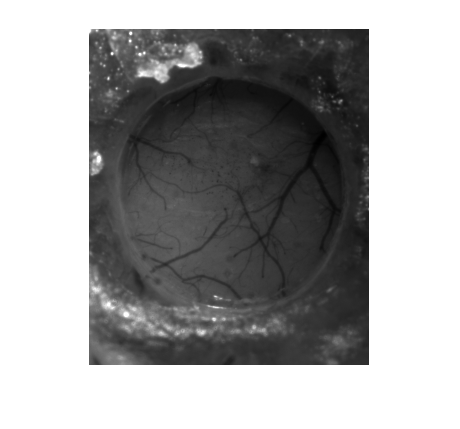

dataFolderPath = 'E:\Data Jeremie\Bilateral Stim and Resting State dataset\M4\M4_rs_10min';
greenMovie = ImagingMovie(dataFolderPath,'green');
greenMovie.correctMotion;

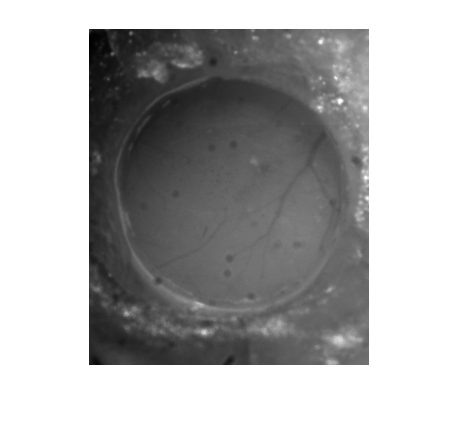

redMovie = ImagingMovie(dataFolderPath,'red');
redMovie.correctMotion;

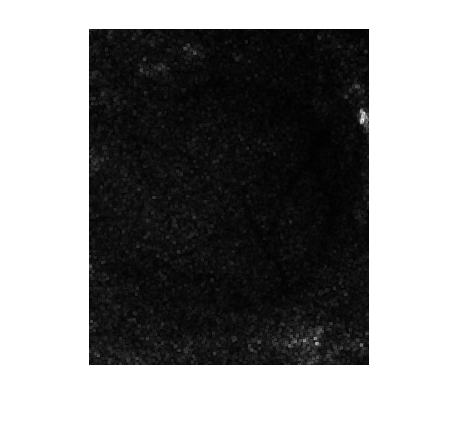

speckleContrastMovie = ImagingMovie(dataFolderPath,'speckle');
speckleContrastMovie.correctMotion;

greenMovie.normalizeByMean;
redMovie.normalizeByMean;
[HbOMovie, HbRMovie] = convertToHb(greenMovie.data,redMovie.data);
speckleContrastMovie.convertToSpeckleContrast(5);
HbOMovie = ImagingMovie(dataFolderPath,'HbO',HbOMovie);
HbRMovie = ImagingMovie(dataFolderPath,'HbR',HbRMovie);
clear greenMovie redMovie
HbOMovie.gaussianFilter(1);
HbRMovie.gaussianFilter(1);
speckleContrastMovie.gaussianFilter(1);
HbOMovie.zscore;
HbRMovie.zscore;
speckleContrastMovie.zscore;
mask = HbOMovie.createMask;
HbOMovie.applyMask(mask);
HbRMovie.applyMask(mask);
speckleContrastMovie.applyMask(mask);

We first analyze the movies by applying a low pass filter with a 0.15 Hz cutoff. 

%Store unfiltered data for later use
HbO_unfiltered = HbOMovie.data;
HbR_unfiltered = HbRMovie.data;
SC_unfiltered = speckleContrastMovie.data;
HbOMovie.bandPassFilter(0.01,0.15);
HbRMovie.bandPassFilter(0.01,0.15);
speckleContrastMovie.bandPassFilter(0.01,0.15);
HbOMatrix = HbOMovie.convertTo2DMatrix(mask);
HbRMatrix = HbRMovie.convertTo2DMatrix(mask);
SCMatrix = speckleContrastMovie.convertTo2DMatrix(mask);

The movies are now analyzed using PCA.

%With Matlab's pca function, rows must correspond to observations, and columns to variables
%(dimensions).
[~,scoresHbO] = pca(HbOMatrix');
[~,scoresHbR] = pca(HbRMatrix');
[~,scoresSC] = pca(SCMatrix');
scoresHbO = scoresHbO'; %Put back into (component by observations) format
scoresHbR = scoresHbR';
scoresSC = scoresSC';

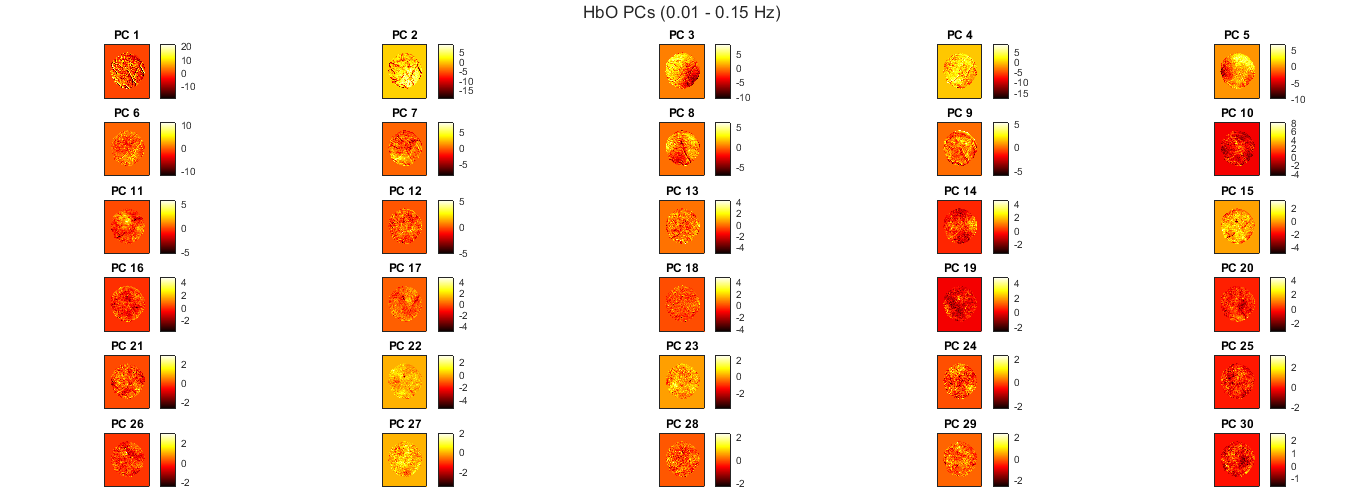

%Display first n PCs (n must be multiple of 5)
n = 30;
figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(n/5,5);
t.TileSpacing = 'compact';
t.Padding = 'none';
t.Title.String = 'HbO PCs (0.01 - 0.15 Hz)';
for i = 1:n
    nexttile;
    map(find(mask))=scoresHbO(i,:);
    imagesc(map);
    title(['PC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

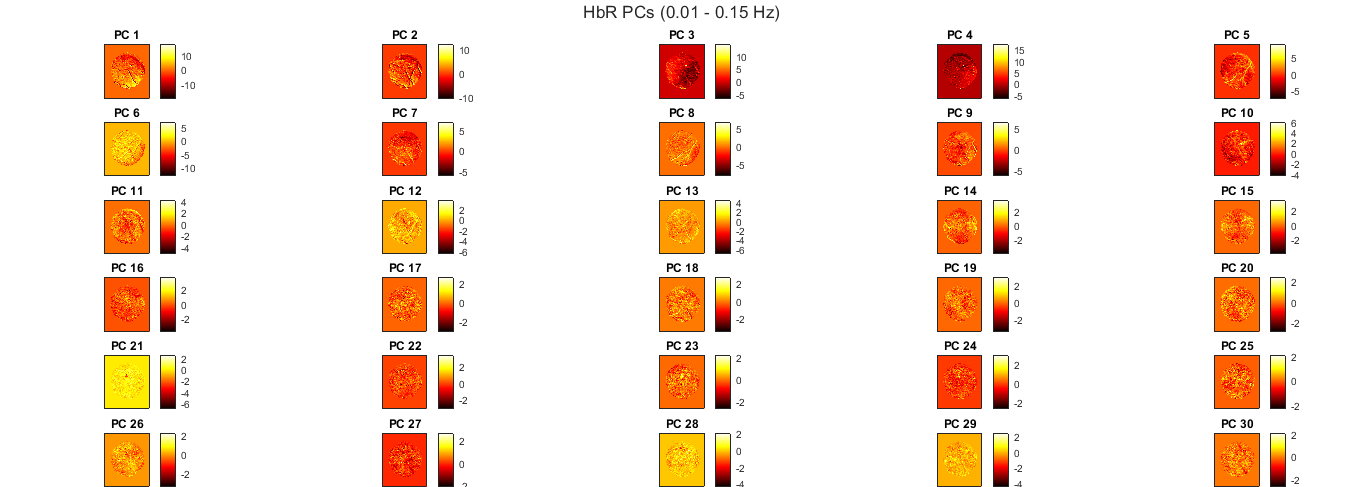


figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(n/5,5);
t.TileSpacing = 'compact';
t.Padding = 'none';
t.Title.String = 'HbR PCs (0.01 - 0.15 Hz)';
for i = 1:n
    nexttile;
    map(find(mask))=scoresHbR(i,:);
    imagesc(map);
    title(['PC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

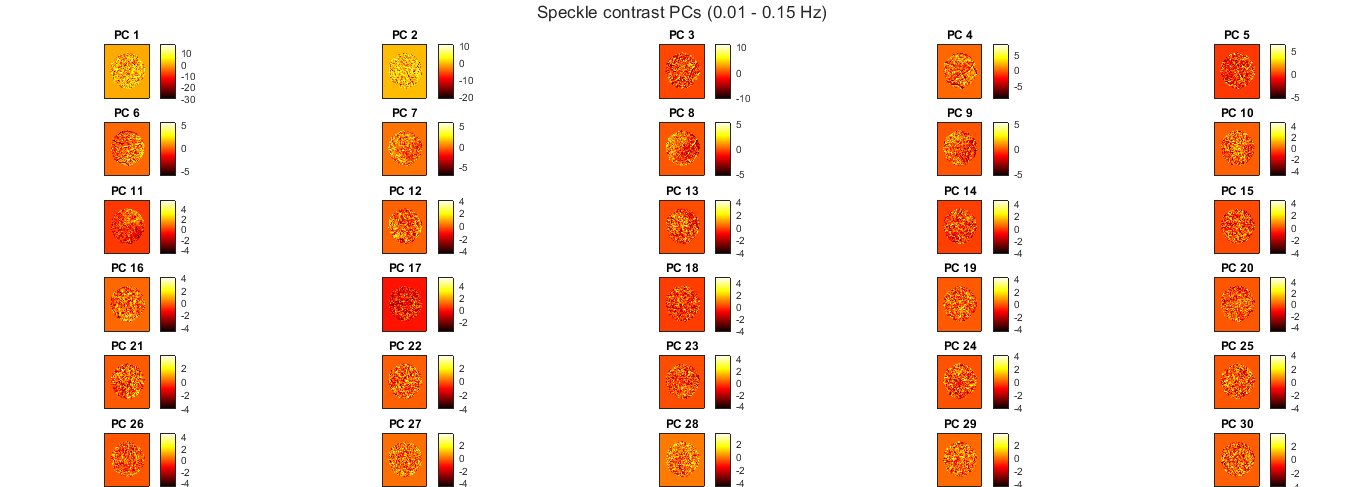


figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(n/5,5);
t.TileSpacing = 'compact';
t.Padding = 'none';
t.Title.String = 'Speckle contrast PCs (0.01 - 0.15 Hz)';
for i = 1:n
    nexttile;    
    map(find(mask))=scoresSC(i,:);
    imagesc(map);
    title(['PC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

The analysis is now repeated with the unfiltered data.

HbO_unfiltered = ImagingMovie(dataFolderPath,'HbO',HbO_unfiltered);
HbR_unfiltered = ImagingMovie(dataFolderPath,'HbR',HbR_unfiltered);
SC_unfiltered = ImagingMovie(dataFolderPath,'speckle',SC_unfiltered);
HbOMatrix = HbO_unfiltered.convertTo2DMatrix(mask);
HbRMatrix = HbR_unfiltered.convertTo2DMatrix(mask);
SCMatrix = SC_unfiltered.convertTo2DMatrix(mask);
[~,scoresHbO] = pca(HbOMatrix');
[~,scoresHbR] = pca(HbRMatrix');
[~,scoresSC] = pca(SCMatrix');
scoresHbO = scoresHbO';
scoresHbR = scoresHbR';
scoresSC = scoresSC';

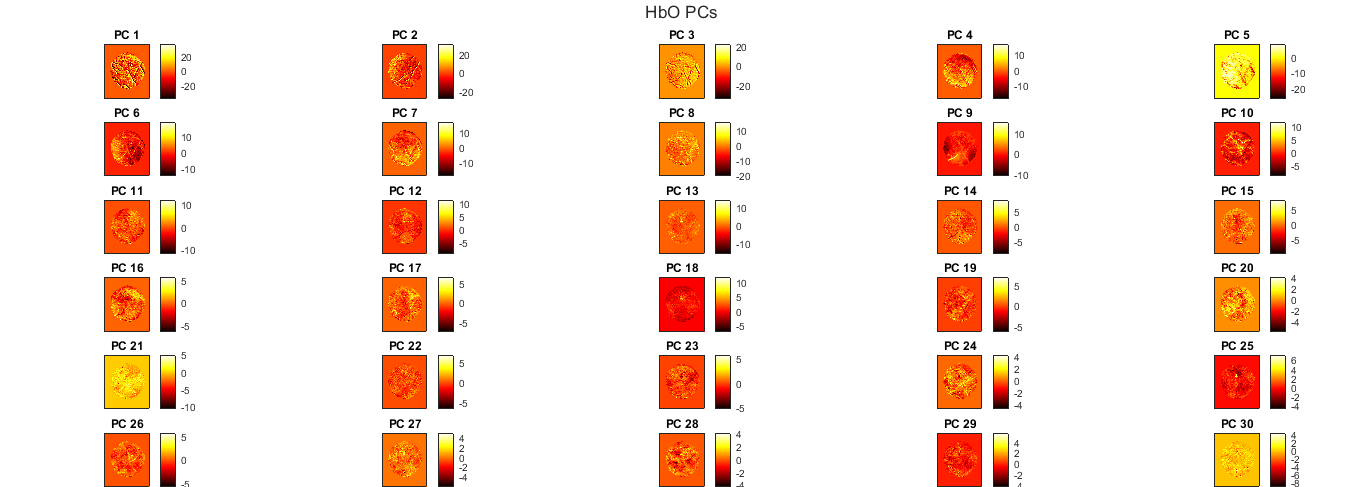

%Display first n PCs (n must be multiple of 5)
n = 30;
figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(n/5,5);
t.TileSpacing = 'compact';
t.Padding = 'none';
t.Title.String = 'HbO PCs (unfiltered data)';
for i = 1:n
    nexttile;
    map(find(mask))=scoresHbO(i,:);
    imagesc(map);
    title(['PC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

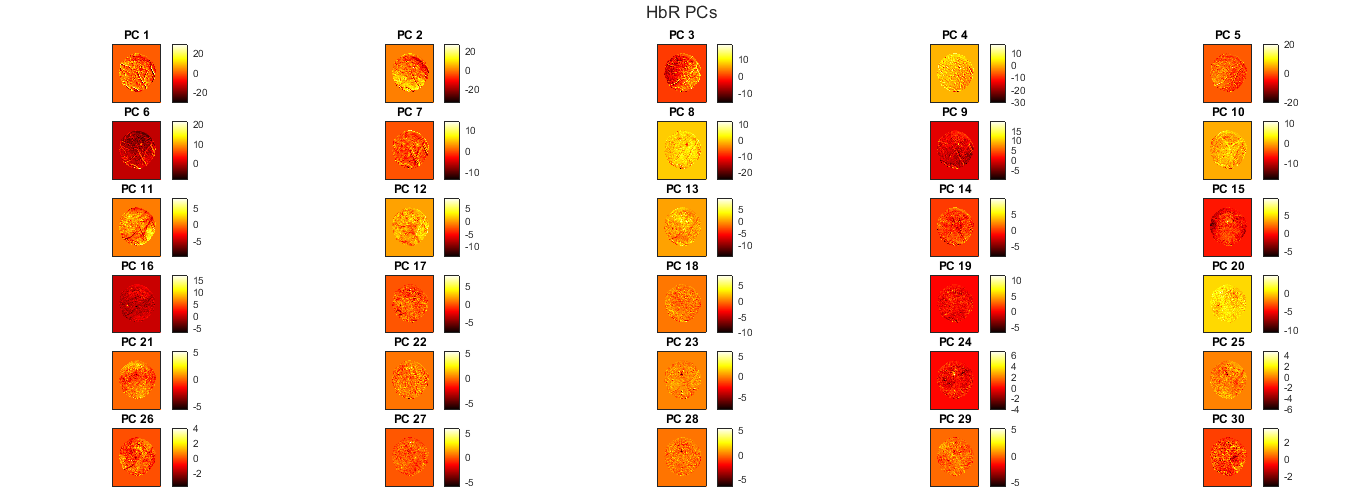


figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(n/5,5);
t.TileSpacing = 'none';
t.Padding = 'none';
t.Title.String = 'HbR PCs (unfiltered data)';
for i = 1:n
    nexttile;    
    map(find(mask))=scoresHbR(i,:);
    imagesc(map);
    title(['PC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

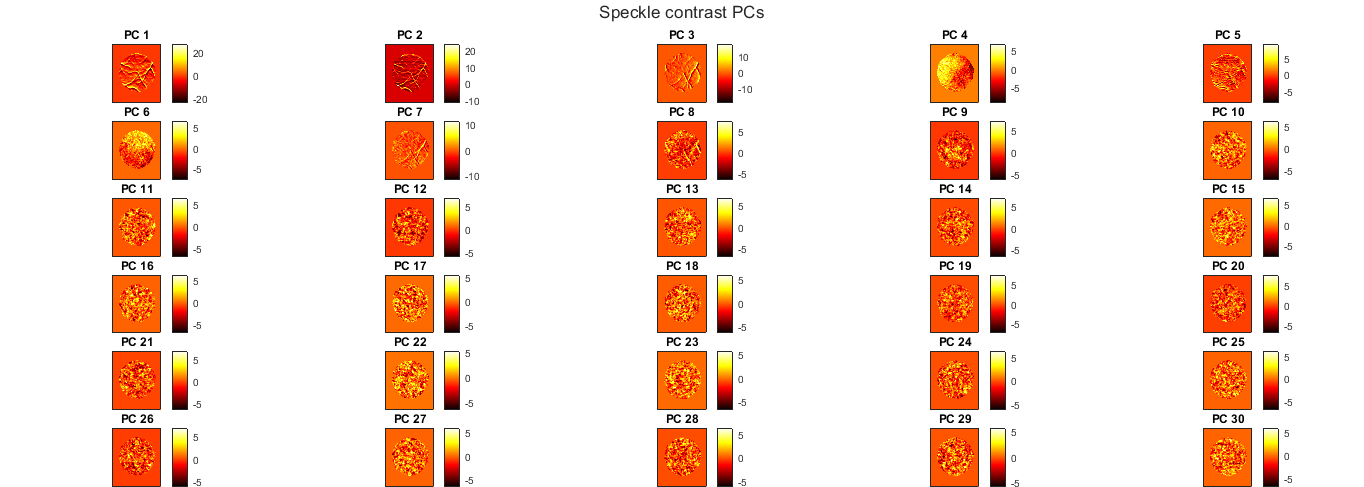


figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(n/5,5);
t.TileSpacing = 'none';
t.Padding = 'none';
t.Title.String = 'Speckle contrast PCs (unfiltered data)';
for i = 1:n
    nexttile;    
    map(find(mask))=scoresSC(i,:);
    imagesc(map);
    title(['PC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

A few observations:

- The speckle contrast PCs are much more defined when using the entire frequency range.

- In both frequency ranges (but more obvious in the filtered signal), there is a PC in which the large vessel signal is anticorrelated to the parenchymal signal. 

- There are often patterns of anticorrelated vessel pairs.

- Some indivudual vessels, or small groups of them, are often seen to be active independently from others.

Independant components are now similarly extracted from the data.

HbOMatrix = HbOMovie.convertTo2DMatrix(mask);
HbRMatrix = HbRMovie.convertTo2DMatrix(mask);
SCMatrix = speckleContrastMovie.convertTo2DMatrix(mask);
%With the fastICA function, rows must correspond to variables (dimensions) and columns to obserations.
n = 10;
[scoresHbO] = fastICA(HbOMatrix,n);
[scoresHbR] = fastICA(HbRMatrix,n);
[scoresSpeckle] = fastICA(SCMatrix,n);

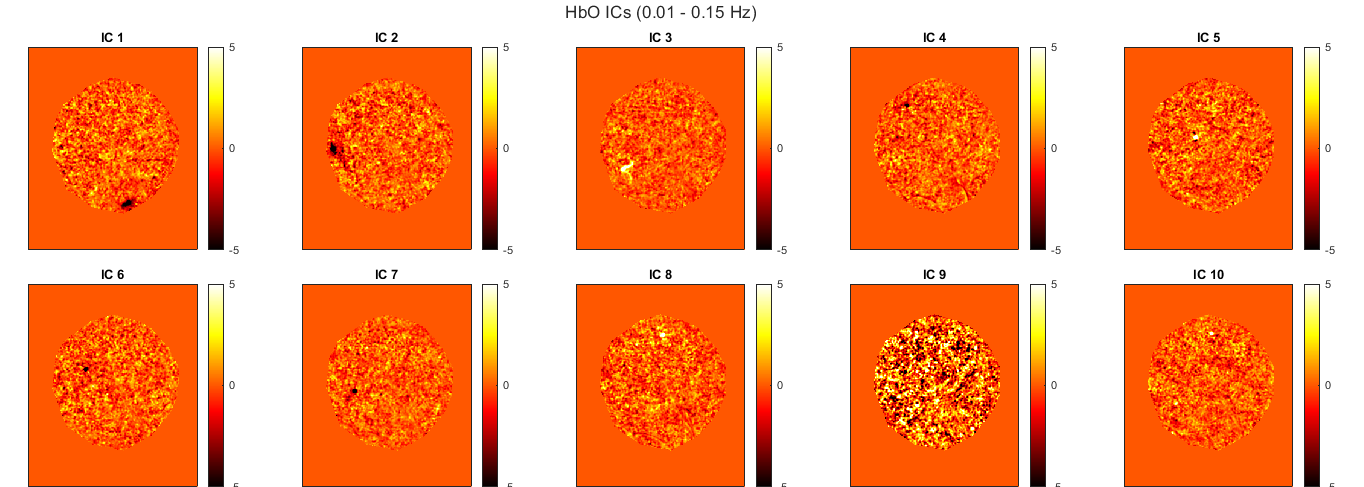

%Display first n ICs
figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'compact';
t.Padding = 'none';
t.Title.String = 'HbO ICs (0.01 - 0.15 Hz)';
for i = 1:n
    nexttile;
    map(find(mask))=scoresHbO(i,:);
    imagesc(map,[-5 5]);
    title(['IC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

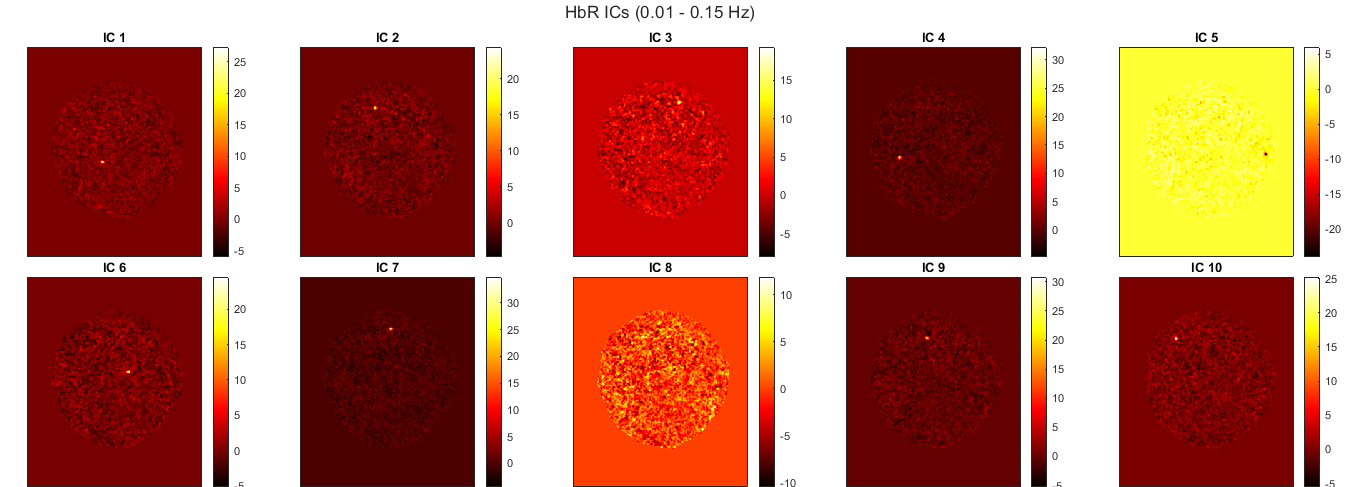


figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'none';
t.Padding = 'none';
t.Title.String = 'HbR ICs (0.01 - 0.15 Hz)';
for i = 1:n
    nexttile;    
    map(find(mask))=scoresHbR(i,:);
    imagesc(map);
    title(['IC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

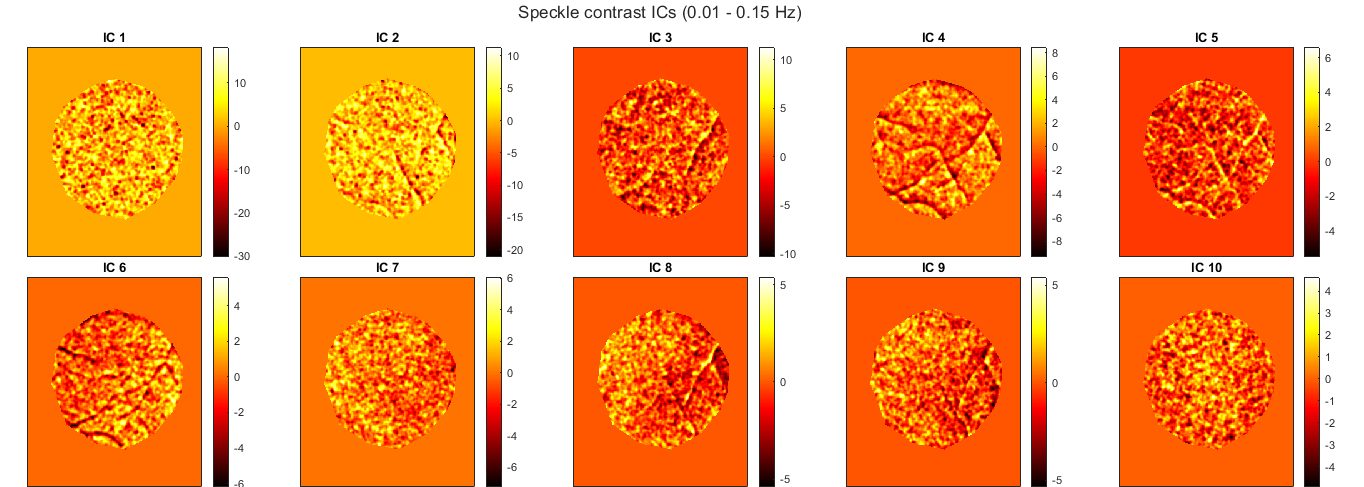


figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'none';
t.Padding = 'none';
t.Title.String = 'Speckle contrast ICs (0.01 - 0.15 Hz)';
for i = 1:n
    nexttile;    
    map(find(mask))=scoresSC(i,:);
    imagesc(map);
    title(['IC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end